# Práctica N°4 Control Biológico.

Autor: Tomás Vidal

### Notas

- Hay que aclarar que se empleó un punto de referencia arbitrario para los diferentes controladores. Además se emplean mediciones de $\mu \left(s\right)$, para lo cual se necesitaria un observador

## Preguntas

- ¿Considero $S_{\textrm{in}} \;$como un parámetro con incertidumbre?

- ¿Agrego pruebas de robustez con rechazo a perturbaciones además?

- ¿Agrego más pruebas de robustez con diferentes variaciones de Ki y Kp?

## Proceso de bioplástico (PHB)


$$\[k_{S1} S + k_N N \rightarrow{r_x} X + k_{P1} P\]

\[k_{S2} S \rightarrow{r_p} P\]$$


El proceso es modelado con las siguientes ecuaciones:


$$\[ \dot{x} = r_x x - Dx \]

\[ \dot{s} = -k_{s1} r_x - k_{s2} r_p + D(s_i - s_j) \]

\[ \dot{N} = -k_N r_x + D(n_i - n) \]

\[ \dot{p} = k_{s2} r_p - Dp \]$$


En forma vectorial:


$$
\left[
\begin{array}{c}
\dot{x} \\
\dot{s} \\
\dot{n} \\
\dot{p}
\end{array}
\right]
=
\left[
\begin{array}{c}
1 & 0 \\ 
-K_{s1} & -K_{s2} \\
-K_{N} & 0 \\
K_{p1}  & 1
\end{array}
\right]
*
\left[
\begin{array}{c}
x \\ s \\ n \\ p
\end{array}
\right]
+ D * \left[
\begin{array}{c}
-x \\ s_{in}-s \\ n_{in}-n \\ -p
\end{array}
\right]$$


Pero si se considera que solo vamos a simular la fase de producción de microorganismos, podemos descartar la variación en el plástico, porque no hay producción del mismo y además podemos tomar que la cantidad de nitrógeno es tanta que siempre está en saturación, por lo que no varía tampoco. Entonces se tiene el siguiente modelo reducido:


$$
\left[
\begin{array}{c}
\dot{x} \\
\dot{s} \\
\end{array}
\right]
=
\left[
\begin{array}{c}
1 \\ 
-K_{s1}
\end{array}
\right]
*
\left[
\begin{array}{c}
x \\ s
\end{array}
\right]
- D * \left[
\begin{array}{c}
x \\ s
\end{array}
\right]$$


Además la matrix K se reduce  a 1 columna porque no hay tasa de producción de plástico, por lo explicado anteriormente.

Este modelo reducido de 2x2 es el que se emplea a continuación para todas las simulaciones.

### Modos de trabajo

Para la primera parte donde se trabaja con controles no lineales, se supone que se tiene un fed-batch, dado que es el caso de aplicación tipico, porque se tiene un crecimiento exponencial, entonces para "linealizar" la entrada es exponencial también.

Para la segunda parte donde se trabaja con un control linealizante, se emplea una alimentación continua, por lo uqe no hay variación del volumen ($\dot{V} =0$)

DatosModeloTP4

sim_hours = 50; % la cantidad de horas que se van a simular
timeStep = 1e-2;

% Configuración de la simulación de Simulink
simConfig.StopTime = num2str(sim_hours);
simConfig.Solver = 'ode1';
simConfig.FixedStep = num2str(timeStep);

Proceso sin ningún controlador (sólo como referencia)

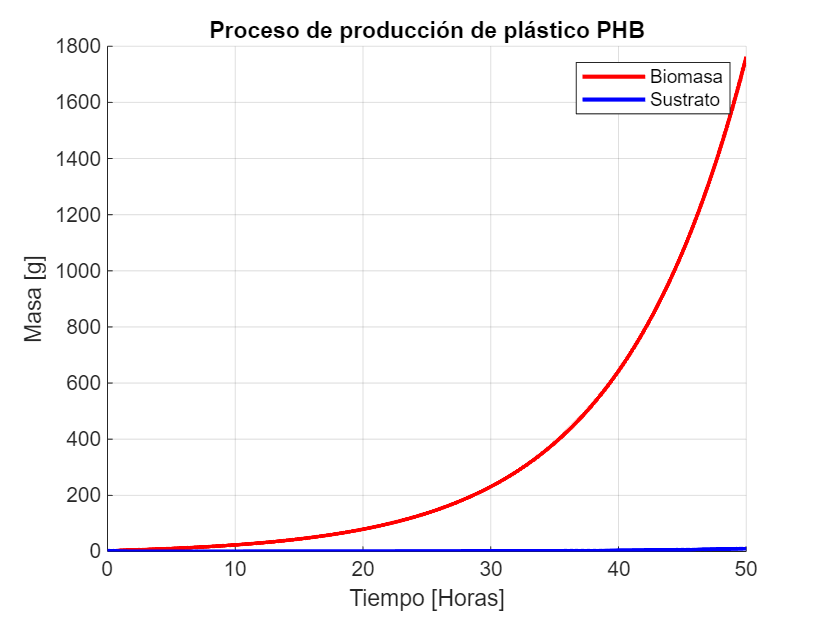

DatosModeloTP4

D=0.1;
params={1};
for i=1:length(params)

    sim_out = sim('simulaciones/TP4_sin_control', simConfig);
    
    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass = reshape(states(:,1), size(time));
    sustrate = reshape(states(:,2), size(time));
    mu = sim_out.mu_s.Data;
    
end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Proceso de producción de plástico PHB');
xlabel('Tiempo [Horas]');
ylabel('Masa [g]');
plot(time, biomass.*volume, 'r', 'LineWidth', 2);
plot(time, sustrate.*volume, 'b', 'LineWidth', 2);
legend('Biomasa', 'Sustrato');

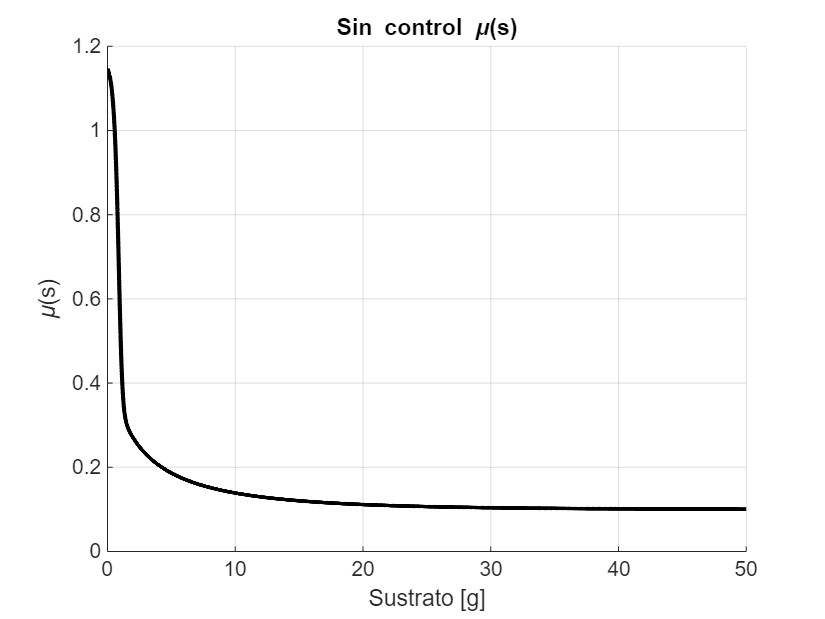


fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Sin control \mu(s)');
xlabel('Sustrato [g]');
ylabel('\mu(s)');
plot(time, mu, 'k', 'LineWidth', 2);


% [mu_freq1] = abs(fft(mu));
% [s_freq1] = abs(fft(sustrate.*volume));
% 
% % Comportamiento en frecuencia de mu
% fig = figure();
% set(fig,'Position',[0 0 800 600]);
% hold on; grid on;
% title('fft(\mu(s))');
% xlabel('fft(Sustrato [g])');
% ylabel('fft(\mu(s))');
% plot(s_freq1, mu_freq1, 'k', 'LineWidth', 2);

## Control con alimentación exponencial

Se hace una alimentación exponencial de masa a lazo abierto. $F_{\textrm{in}} ={\lambda \;X}_0 \;e^{{\textrm{mu}}_r t}$

el punto de referencia se calcula considerando un $s_r$ y luego calculando $\mu_r =\mu \left(s_r \right)$

DatosModeloTP4

s_r=0.27; % s de referencia a operar
mu_r=0.0845; % mu de referencia a operar

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.v0=v0;
modelParameters.s_r = 0.126;
modelParameters.mu_r=mu_r;

params={[s_r, mu_r]};
mus=cell(length(params));
sustrates=cell(length(params));
error=cell(length(params));
MSE=cell(length(params));
for i=1:length(params)

    modelParameters.s_r = params{i}(1);
    modelParameters.mu_r=params{i}(2);

    % fprintf('Sr=%.3f,mur=%.3f\n', params{i}(1),params{i}(2));

    sim_out = sim('simulaciones/TP4_control_exp', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass = reshape(states(:,1), size(time));
    sustrates{i} = reshape(states(:,2), size(time)).*volume;
    Do = sim_out.Do.Data;
    mus{i} = sim_out.mu_s.Data;

    mu_r_vector = ones(1, length(mus{i}))*mu_r;
 
    error{i}=(mu_r_vector-mus{i});
    MSE{i} = immse(reshape(mu_r_vector, size(mus{i})), mus{i});
end

Resultados

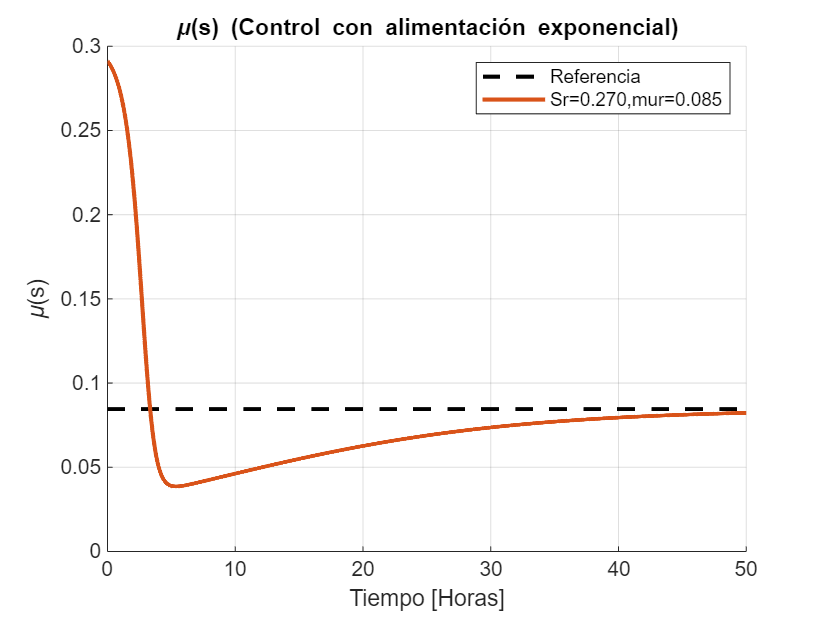

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('\mu(s) (Control con alimentación exponencial)');
xlabel('Tiempo [Horas]');
ylabel('\mu(s)');
plot(time, mu_r_vector, 'k--', 'LineWidth', 2);
plot(time, mus{1}, 'LineWidth', 2);

legend('Referencia', sprintf('Sr=%.3f,mur=%.3f', params{1}(1),params{1}(2)));


% fig = figure();
% set(fig,'Position',[0 0 800 600]);
% hold on; grid on;
% title('Sustrato');
% xlabel('Tiempo [Horas]');
% ylabel('Sustrato [g]');
% plot(time, sustrates{1}, 'LineWidth', 2);
% 
% legend(sprintf('Sr=%.3f,mur=%.3f', params{1}(1),params{1}(2)));

Errores relativos

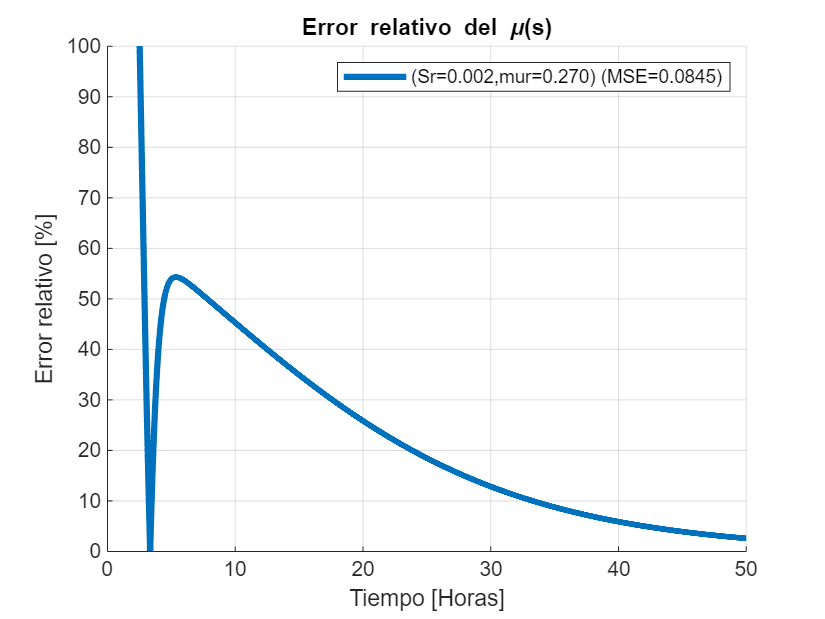

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo del \mu(s)');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error{1}), mu_r_vector), 'LineWidth', 3);

legend(sprintf('(Sr=%.3f,mur=%.3f) (MSE=%.4f)', MSE{1}, params{1}(1), params{1}(2)));

#### Conclusiones:

El error se estaciona, pero se tiene mucho error inicial y tiene una dinámica muy lenta (aprox 50 horas), además si hay variaciones en los parámetros probablemente no sea muy efectivo el control (esto se verifica a continuación).

## Variaciones en los parámetros

### Incertidumbre en x0

Variaciones en las condiciones iniciales:

DatosModeloTP4

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.s_r = 0.1259;
modelParameters.v0=v0;
modelParameters.mu_r=mu_r;

params={x0*(1.2),x0*(0.8)}; % más/menos 20% del x0
mus=cell(length(params));
error=cell(length(params));
MSE=cell(length(params));
for i=1:length(params)

    modelParameters.x0=params{i};

    sim_out = sim('simulaciones/TP4_control_exp', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass = reshape(states(:,1), size(time));
    sustrates = reshape(states(:,2), size(time)).*volume;
    Do = sim_out.Do.Data;
    mus{i} = sim_out.mu_s.Data;

    mu_r_vector = ones(1, length(mus{i}))*mu_r;
 
    error{i}=(mu_r_vector-mus{i});
    MSE{i} = immse(reshape(mu_r_vector, size(mus{i})), mus{i});
end

Ahora se muestran los resultados, comparando el caso cuando se tiene variaciones en las condiciones iniciales y como los controadores empleados responden a estas variaciones, es decir su robustez.

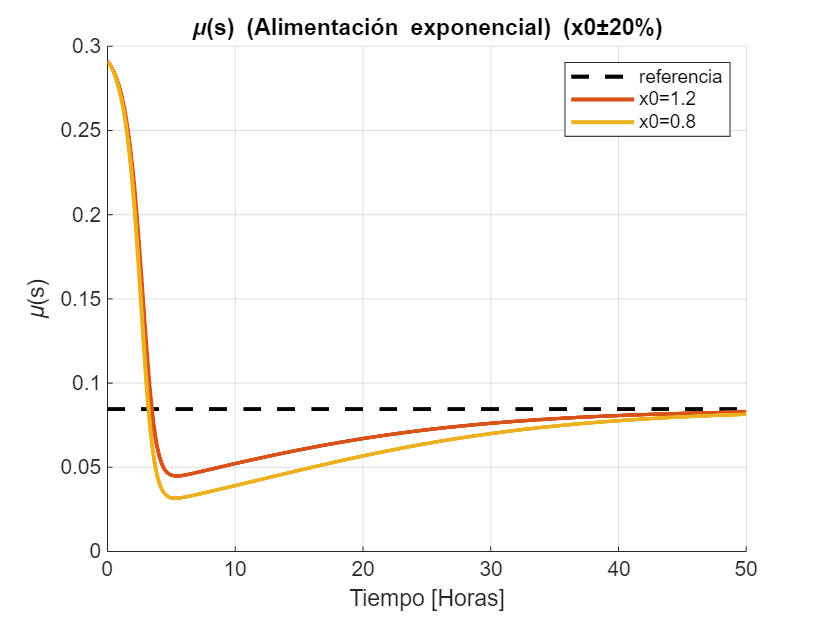

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('\mu(s) (Alimentación exponencial) (x0±20%)');
xlabel('Tiempo [Horas]');
ylabel('\mu(s)');
plot(time, mu_r_vector, 'k--', 'LineWidth', 2);
plot(time, mus{1}, 'LineWidth', 2);
plot(time, mus{2}, 'LineWidth', 2);

legend('Referencia' ...
    ,sprintf('x0=%.1f', params{1}), ...
    sprintf('x0=%.1f', params{2}));

Errores relativos

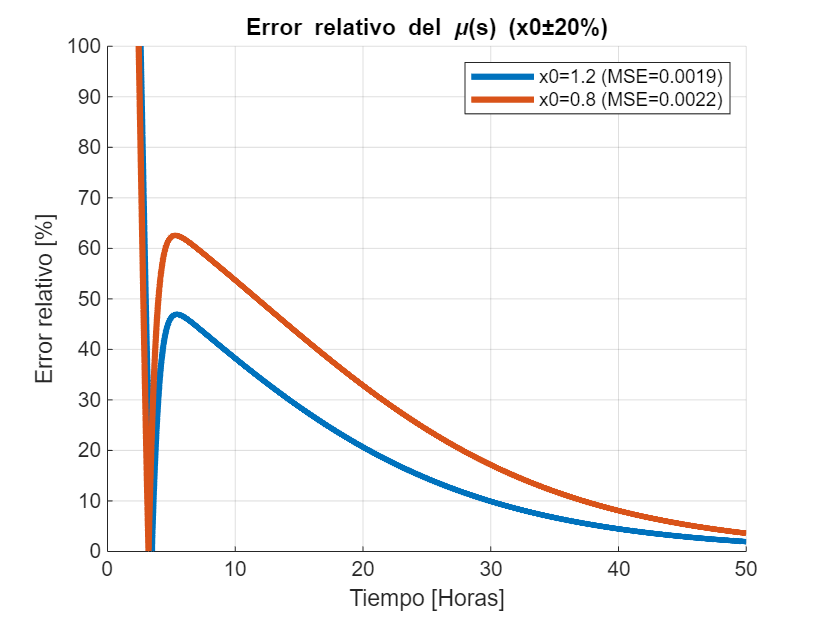

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo del \mu(s) (x0±20%)');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error{1}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{2}), mu_r_vector), 'LineWidth', 3);

legend(sprintf('x0=%.1f (MSE=%.4f)', params{1}, MSE{1}), ...
    sprintf('x0=%.1f (MSE=%.4f)', params{2}, MSE{2}));

### Conclusiones

Al igual que antes el error se termina estacionando y sigue teniendo una dinámica muy lenta, pero además ahora, debido a la variación de parámetros el error varía en un 14% (MSE) aproximadamente, por lo que no es robusto ante variaciones de este parámetro

### Incertidumbre en ks1 

Ahora hago lo mismo que antes pero variando $k_{\textrm{s1}}$

DatosModeloTP4

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.v0=v0;
modelParameters.s_r = 0.1259;
modelParameters.mu_r=mu_r;

params_ks={ks1*(1.2),ks1*(0.8)}; % más/menos 20% del ks1
mus_ks=cell(length(params_ks));
error_ks=cell(length(params_ks));
MSE_ks=cell(length(params_ks));
for i=1:length(params_ks)
    modelParameters.K = [1;-params_ks{i}];

    sim_out = sim('simulaciones/TP4_control_exp', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass = reshape(states(:,1), size(time));
    sustrate_ks = reshape(states(:,2), size(time)).*volume;
    Do = sim_out.Do.Data;
    mus_ks{i} = sim_out.mu_s.Data;

    mu_r_vector = ones(1, length(mus_ks{i}))*mu_r;
 
    error_ks{i}=(mu_r_vector-mus_ks{i});
    MSE_ks{i} = immse(reshape(mu_r_vector, size(mus_ks{i})), mus_ks{i});
end

Ahora se muestran las gráficas

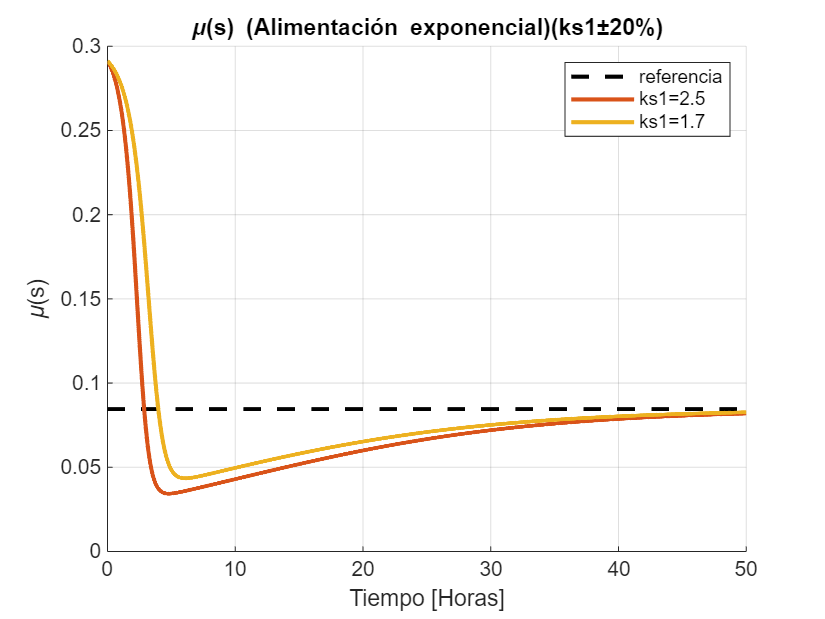

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('\mu(s) (Alimentación exponencial)(ks1±20%)');
xlabel('Tiempo [Horas]');
ylabel('\mu(s)');
plot(time, mu_r_vector, 'k--', 'LineWidth', 2);
plot(time, mus_ks{1}, 'LineWidth', 2);
plot(time, mus_ks{2}, 'LineWidth', 2);

legend('Referencia' ...
    ,sprintf('ks1=%.1f', params_ks{1}), ...
    sprintf('ks1=%.1f', params_ks{2}));

Y las del error relativo son:

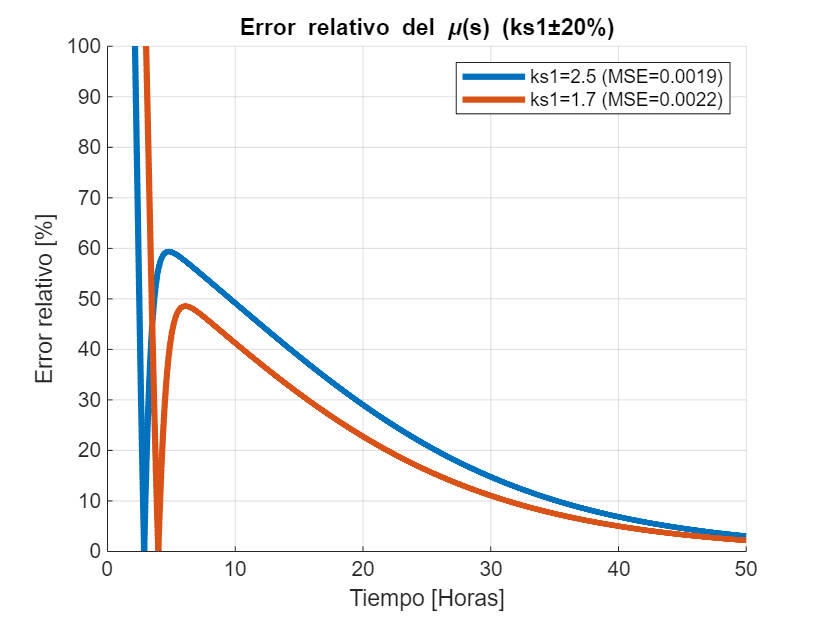

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo del \mu(s) (ks1±20%)');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error_ks{1}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error_ks{2}), mu_r_vector), 'LineWidth', 3);

legend(sprintf('ks1=%.1f (MSE=%.4f)', params_ks{1}, MSE_ks{1}), ...
    sprintf('ks1=%.1f (MSE=%.4f)', params_ks{2}, MSE_ks{2}));

#### Conclusiones

Se tienen resultados similares, la forma en que el error se da varía ligeramente (hay más error al inicio, y luego menos, en comparación al caso anterior).

## Control exponencial con términos kp y ki

### Control proporcional al error

Ahora al controlador anterior se le añade un término que es no lineal y proporcional al error (la ganancia de proporción es kp), tal que cuando se aplique corrija linealmente el error. Se varía kp en la simulación para analizar su efecto, que debería disminuir el error a medida que se aumenta kp.

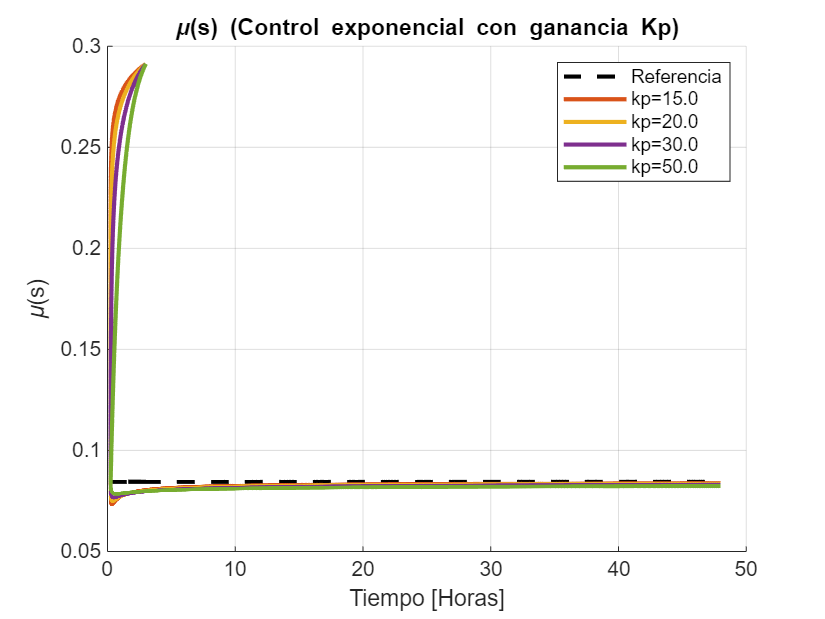

DatosModeloTP4

sim_hours2 = 90;
timeStep2 = 0.8*1e-2;
simConfig.StopTime = num2str(sim_hours2);
simConfig.FixedStep = num2str(timeStep2);

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.s_r = 0.1259;
modelParameters.mu_r=mu_r;
% modelParameters.kp=0.1; % factor proporcional

params={15, 20, 30, 50};
mus=cell(length(params));
error=cell(length(params));
MSE=cell(length(params));
for i=1:length(params)
    modelParameters.kp=params{i};

    sim_out = sim('simulaciones/TP4_control_kp', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass = reshape(states(:,1), size(time));
    sustrate = reshape(states(:,2), size(time)).*volume;
    Do = sim_out.Do.Data;
    mus{i} = sim_out.mu_s.Data;

    mu_r_vector = ones(1, length(mus{i}))*mu_r;
    
    error{i}=(mu_r_vector-mus{i});
    MSE{i} = immse(reshape(mu_r_vector, size(mus{i})), mus{i});

end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('\mu(s) (Control exponencial con ganancia Kp)');
xlabel('Tiempo [Horas]');
ylabel('\mu(s)');
plot(sustrate, mu_r_vector, 'k--', 'LineWidth', 2);
plot(sustrate, mus{1}, 'LineWidth', 2);
plot(sustrate, mus{2}, 'LineWidth', 2);
plot(sustrate, mus{3}, 'LineWidth', 2);
plot(sustrate, mus{4}, 'LineWidth', 2);

legend('Referencia' ...
    ,sprintf('kp=%.1f', params{1}), ...
    sprintf('kp=%.1f', params{2}), ...
    sprintf('kp=%.1f', params{3}), ...
    sprintf('kp=%.1f', params{4}));

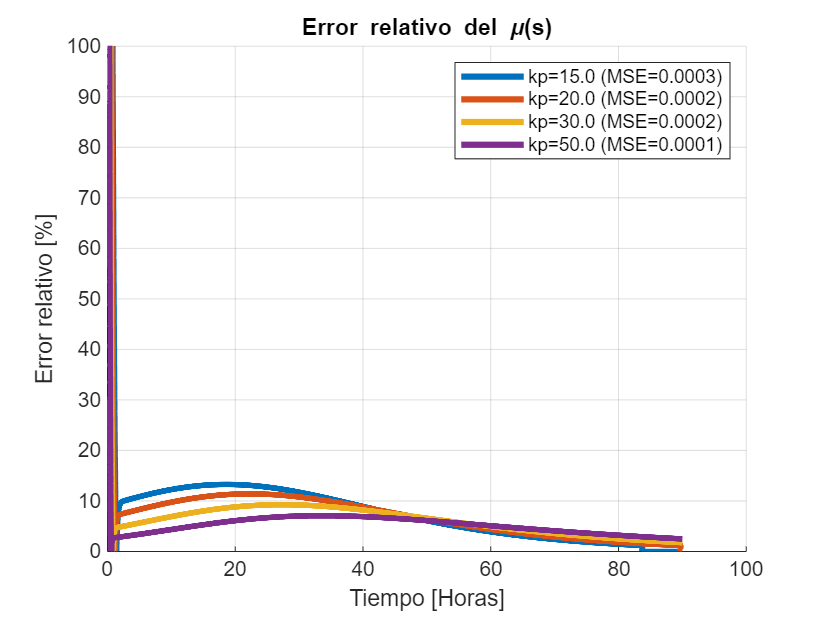


% Error relativo
fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo del \mu(s)');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error{1}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{2}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{3}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{4}), mu_r_vector), 'LineWidth', 3);

legend(sprintf('kp=%.1f (MSE=%.4f)', params{1}, MSE{1}), ...
    sprintf('kp=%.1f (MSE=%.4f)', params{2}, MSE{2}), ...
    sprintf('kp=%.1f (MSE=%.4f)', params{3}, MSE{3}), ...
    sprintf('kp=%.1f (MSE=%.4f)', params{4}, MSE{4}));

#### Conclusiones

Ahora se puede observar que el error a disminuido notablemente, pero todavía se puede ver un error al estado estacionario, que disminuye a medida que se aumenta la ganancia $k_p$, por eso a continuación lo elimino con un integrador, para no tener que incrementar demasiado la ganancia $k_p$

### Proporcional integrativo

Ahora agrego un término integrativo al controlador anterior, es decir que se tiene un término no lineal, que acumula el error y lo pondera con una ganancia ki, que se varía en la simulación para analizar su efecto.

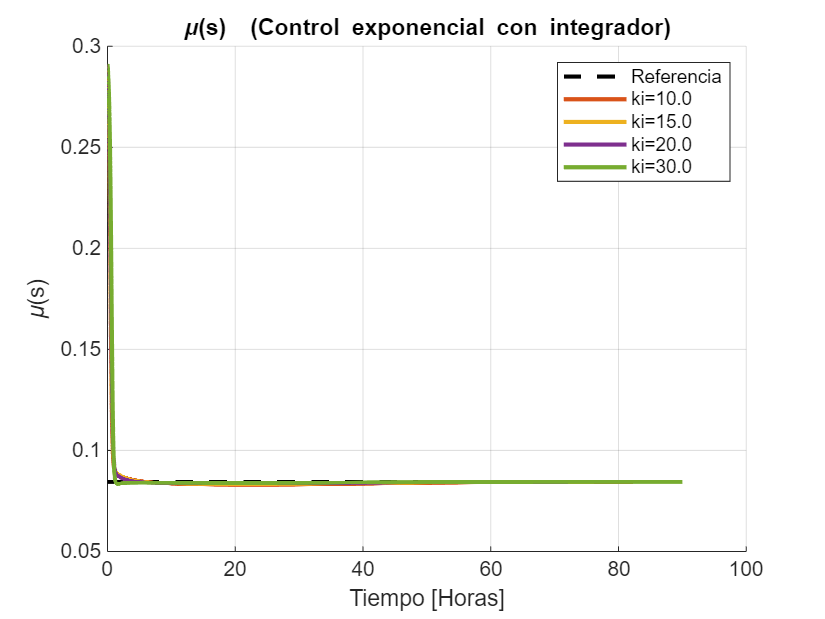

DatosModeloTP4

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.s_r = 0.1259;
modelParameters.mu_r=mu_r;
modelParameters.kp=30; % factor proporcional
% modelParameters.ki=0.1; % factor integrativa
e0=mu_r*1.5;

params={10, 15, 20, 30};
mus=cell(length(params));
error=cell(length(params));
MSE=cell(length(params));
for i=1:length(params)
    modelParameters.ki=params{i};

    sim_out = sim('simulaciones/TP4_control_int', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass = reshape(states(:,1), size(time));
    sustrate = reshape(states(:,2), size(time)).*volume;
    Do = sim_out.Do.Data;
    mus{i} = sim_out.mu_s.Data;

    mu_r_vector = ones(1, length(mus{i}))*mu_r;
    
    error{i}=(mu_r_vector-mus{i});
    MSE{i} = immse(reshape(mu_r_vector, size(mus{i})), mus{i});

end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('\mu(s)  (Control exponencial con integrador)');
xlabel('Tiempo [Horas]');
ylabel('\mu(s)');
plot(time, mu_r_vector, 'k--', 'LineWidth', 2);
plot(time, mus{1}, 'LineWidth', 2);
plot(time, mus{2}, 'LineWidth', 2);
plot(time, mus{3}, 'LineWidth', 2);
plot(time, mus{4}, 'LineWidth', 2);

legend('Referencia' ...
    ,sprintf('ki=%.1f', params{1}), ...
    sprintf('ki=%.1f', params{2}), ...
    sprintf('ki=%.1f', params{3}), ...
    sprintf('ki=%.1f', params{4}));

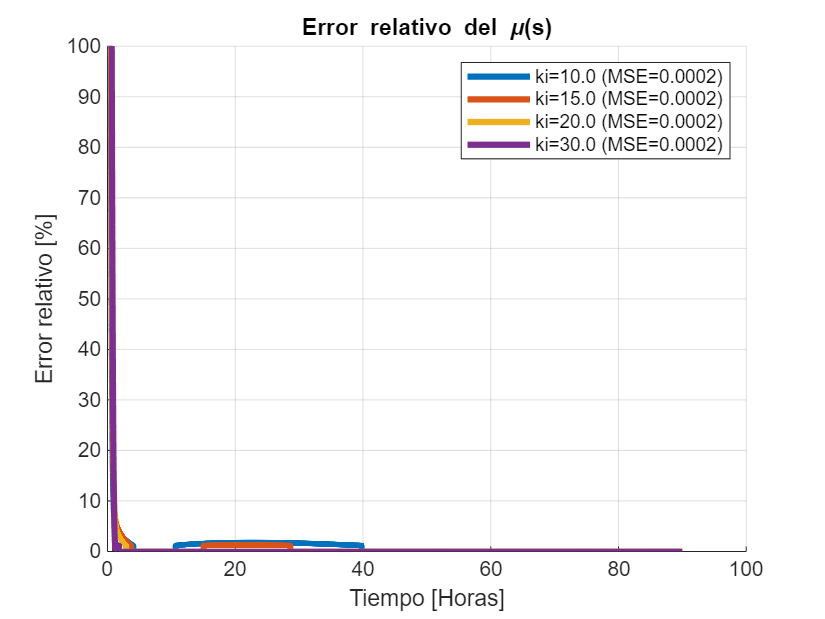


% Error relativo
fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo del \mu(s)');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error{1}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{2}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{3}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{4}), mu_r_vector), 'LineWidth', 3);

legend(sprintf('ki=%.1f (MSE=%.4f)', params{1}, MSE{1}), ...
    sprintf('ki=%.1f (MSE=%.4f)', params{2}, MSE{2}), ...
    sprintf('ki=%.1f (MSE=%.4f)', params{3}, MSE{3}), ...
    sprintf('ki=%.1f (MSE=%.4f)', params{4}, MSE{4}));

#### Conclusiones

Se puede ver que ahora con el término integrativo del error se elimina el error al estado estacionario, la convergencia a la referencia es eventual, y toma aproximadamente 5 horas (dependiendo del ki y kp elegidos), pero la convergencia es mucho más rápida y eventual a diferencia de antes.

## Robustez del controlador a lazo cerrado (integrador)

Se comprueba la robustez al igual que antes, pero solo para el caso donde se tiene un integrador

### Variaciones en x0

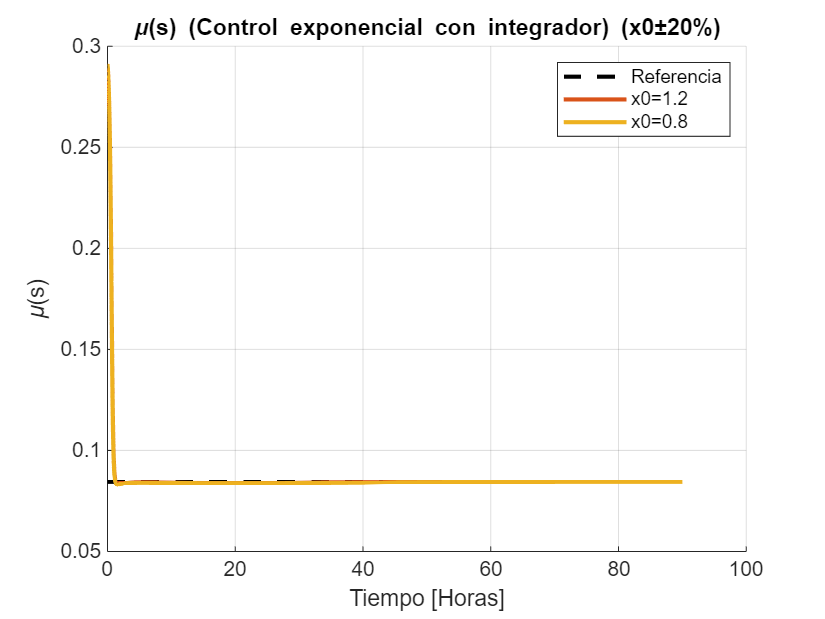

DatosModeloTP4

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.s_r = 0.1259;
modelParameters.mu_r=mu_r;
modelParameters.kp=30; % factor proporcional
modelParameters.ki=30; % factor integrativo
e0=mu_r*1.5;

params_x0={x0*(1.2),x0*(0.8)}; % más/menos 20% del x0
mus=cell(length(params_x0));
error=cell(length(params_x0));
MSE=cell(length(params_x0));
for i=1:length(params_x0)
    modelParameters.x0=params_x0{i};

    sim_out = sim('simulaciones/TP4_control_int', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass = reshape(states(:,1), size(time));
    sustrate = reshape(states(:,2), size(time)).*volume;
    Do = sim_out.Do.Data;
    mus{i} = sim_out.mu_s.Data;

    mu_r_vector = ones(1, length(mus{i}))*mu_r;
    
    error{i}=(mu_r_vector-mus{i});
    MSE{i} = immse(reshape(mu_r_vector, size(mus{i})), mus{i});

end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('\mu(s) (Control exponencial con integrador) (x0±20%)');
xlabel('Tiempo [Horas]');
ylabel('\mu(s)');
plot(time, mu_r_vector, 'k--', 'LineWidth', 2);
plot(time, mus{1}, 'LineWidth', 2);
plot(time, mus{2}, 'LineWidth', 2);

legend('Referencia' ...
    ,sprintf('x0=%.1f', params_x0{1}), ...
    sprintf('x0=%.1f', params_x0{2}));

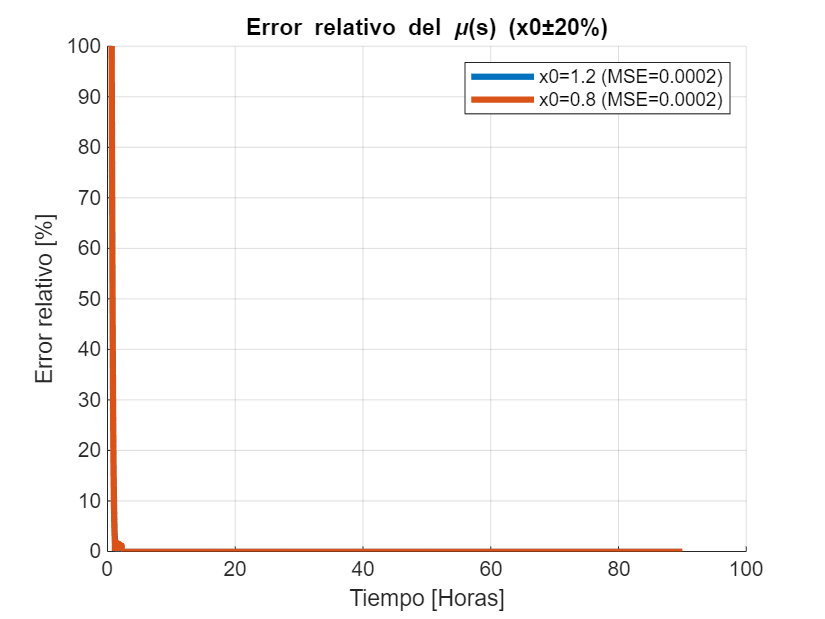


% Error relativo
fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo del \mu(s) (x0±20%)');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error{1}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{2}), mu_r_vector), 'LineWidth', 3);

legend(sprintf('x0=%.1f (MSE=%.4f)', params_x0{1}, MSE{1}), ...
    sprintf('x0=%.1f (MSE=%.4f)', params_x0{2}, MSE{2}));

#### Conclusiones

Se puede ver que este controlador es mucho más robusto que el que no tiene término con kp ni ki, ya que aunque variaciones, son inperceptibles prácticamente.

### Variaciones en ks1

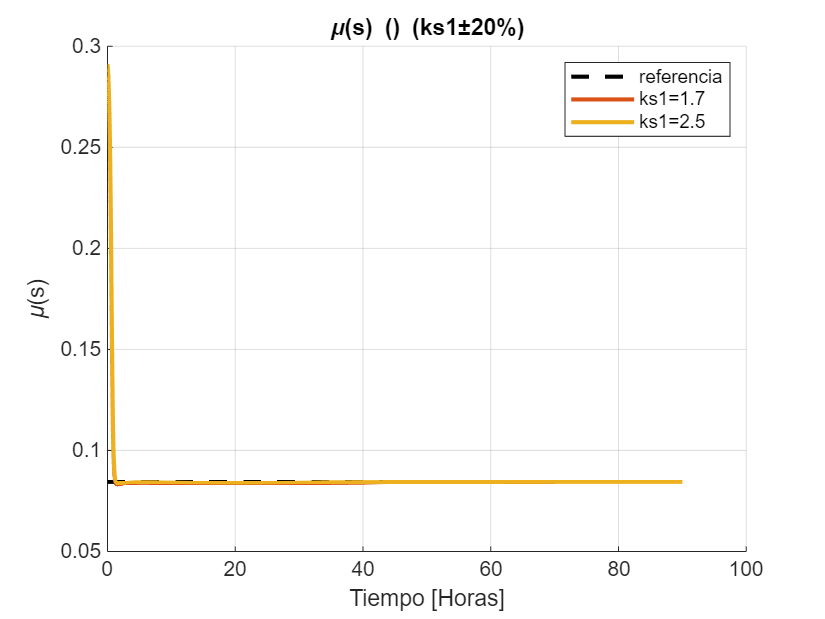

DatosModeloTP4

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.s_r = 0.1259;
modelParameters.mu_r=mu_r;
modelParameters.kp=30; % factor proporcional
modelParameters.ki=30; % factor integrativo
e0=mu_r*1.5;

params={ks1*(0.8), ks1*(1.2)};
mus=cell(length(params));
error=cell(length(params));
MSE=cell(length(params));
for i=1:length(params)
    modelParameters.ks1=params{i};

    sim_out = sim('TP4_control_int', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass = reshape(states(:,1), size(time));
    sustrate = reshape(states(:,2), size(time)).*volume;
    Do = sim_out.Do.Data;
    mus{i} = sim_out.mu_s.Data;

    mu_r_vector = ones(1, length(mus{i}))*mu_r;
    
    error{i}=(mu_r_vector-mus{i});
    MSE{i} = immse(reshape(mu_r_vector, size(mus{i})), mus{i});

end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('\mu(s) () (ks1±20%)');
xlabel('Tiempo [Horas]');
ylabel('\mu(s)');
plot(time, mu_r_vector, 'k--', 'LineWidth', 2);
plot(time, mus{1}, 'LineWidth', 2);
plot(time, mus{2}, 'LineWidth', 2);

legend('Referencia' ...
    ,sprintf('ks1=%.1f', params{1}), ...
    sprintf('ks1=%.1f', params{2}));

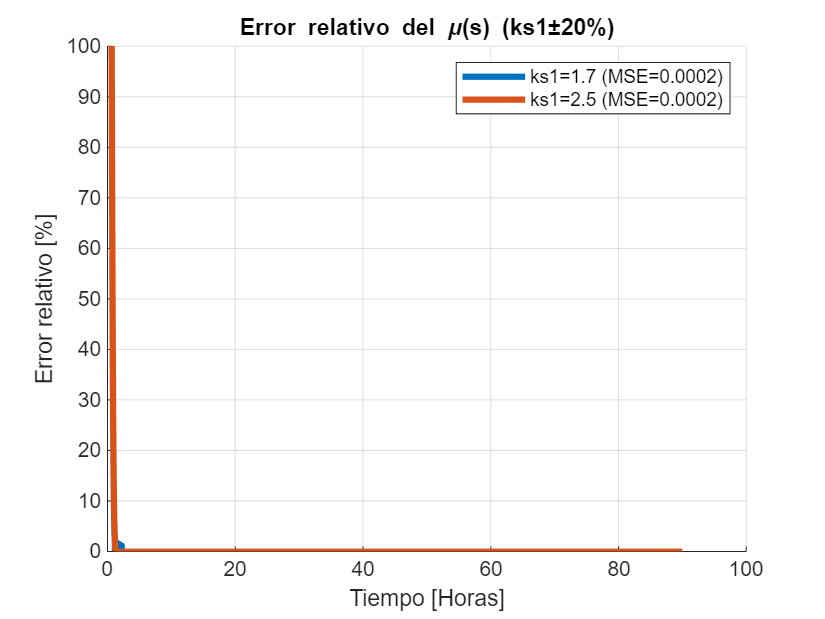


% Error relativo
fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo del \mu(s) (ks1±20%)');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error{1}), mu_r_vector), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{2}), mu_r_vector), 'LineWidth', 3);

legend(sprintf('ks1=%.1f (MSE=%.4f)', params{1}, MSE{1}), ...
    sprintf('ks1=%.1f (MSE=%.4f)', params{2}, MSE{2}));

#### Conclusiones

Al igual que antes se tiene robustez ante variaciones de este parámetro, ya que se termina convergiendo al valor en el mismo tiempo que antes.

### Rechazo a perturbaciones

Se analiza el rechazo a perturbaciones del controlador anterior (con término ki y kp), para lo que se hace una variación del 20% en la dilución.

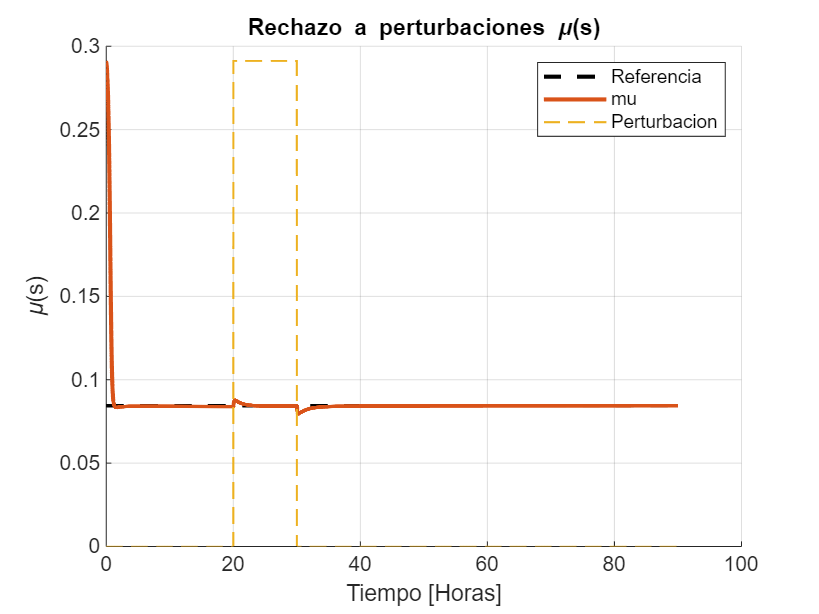

DatosModeloTP4

% Parámetros de la perturbación
disturbanceParameters.start = 20;
disturbanceParameters.end = 30;
disturbanceParameters.percentage = 0.2;

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.s_r = 0.1259;
modelParameters.mu_r=mu_r;
modelParameters.kp=30; % factor proporcional
modelParameters.ki=30; % factor integrativo
modelParameters.ks1=ks1;
e0=mu_r*1.5;

params={0};
mus=cell(length(params));
error=cell(length(params));
MSE=cell(length(params));
for i=1:length(params)
    % modelParameters.ks1=params{i};

    sim_out = sim('TP4_control_int_rech', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass = reshape(states(:,1), size(time));
    sustrate = reshape(states(:,2), size(time)).*volume;
    Do = sim_out.Do.Data;
    mus{i} = sim_out.mu_s.Data;
    disturbance = sim_out.disturbance.Data;

    mu_r_vector = ones(1, length(mus{i}))*mu_r;
    
    error{i}=(mu_r_vector-mus{i});
    MSE{i} = immse(reshape(mu_r_vector, size(mus{i})), mus{i});

end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Rechazo a perturbaciones \mu(s)');
xlabel('Tiempo [Horas]');
ylabel('\mu(s)');
plot(time, mu_r_vector, 'k--', 'LineWidth', 2);
plot(time, mus{1}, 'LineWidth', 2);
plot(time, (disturbance/disturbanceParameters.percentage)*max(mus{1}), '--', 'LineWidth', 1);

legend('Referencia', 'mu', 'Perturbacion');

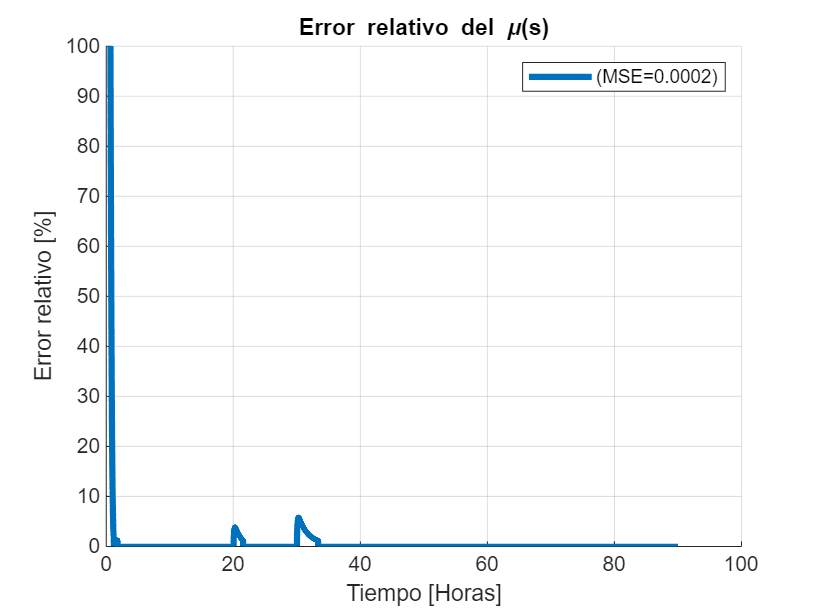


% Error relativo
fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo del \mu(s)');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error{1}), mu_r_vector), 'LineWidth', 3);

legend(sprintf('(MSE=%.4f)', MSE{1}));

#### Conclusiones

Al igual que antes se tiene una gran robustez y performance, más adelante se lo compara con otro tipo de controlador para ver que tan bueno en realidad es.

## Control linealizante

Se quiere regular la concentración de sustrato implementando un control linealizante

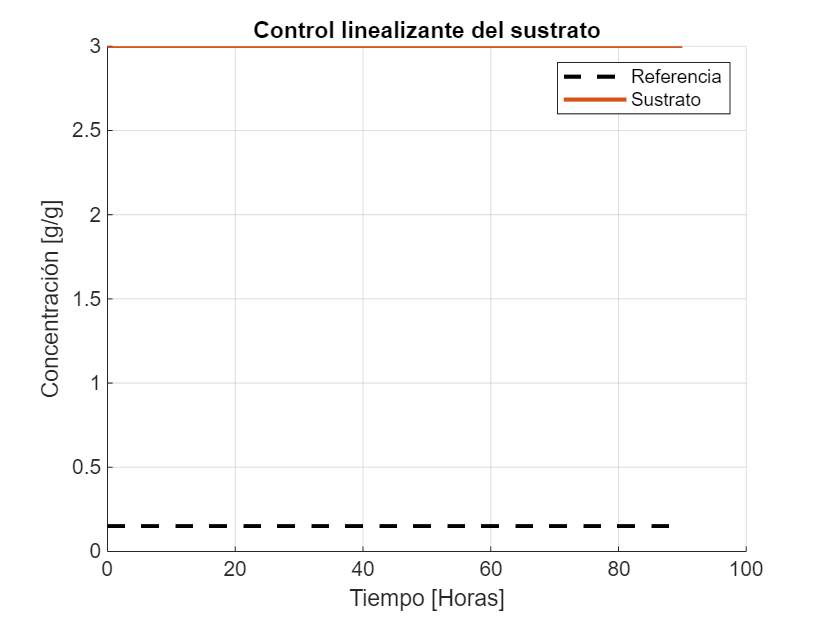

DatosModeloTP4

% referencia del sustrato (s*)
s_r=0.15; 

modelParameters.s_in=s_in;
modelParameters.s_r = s_r;
modelParameters.mu_r=mu_r;

params={1};
sustrates=cell(length(params));
biomass=cell(length(params));
error=cell(length(params));
MSE=cell(length(params));
for i=1:length(params)

    sim_out = sim('simulaciones/TP4_control_linealizante', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass{i} = reshape(states(:,1), size(time));
    sustrates{i} = reshape(states(:,2), size(time));
    Do = sim_out.Do.Data;
    mu = sim_out.mu_s.Data;

    sustrate_vector_r = ones(length(sustrates{i}), 1)*s_r;
    
    error{i}=(sustrate_vector_r-sustrates{i});
    MSE{i} = immse(reshape(sustrate_vector_r, size(sustrates{i})), sustrates{i});

end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Control linealizante del sustrato');
xlabel('Tiempo [Horas]');
ylabel('Concentración [g/g]');
plot(time, sustrate_vector_r, 'k--', 'LineWidth', 2);
plot(time, sustrates{1}, 'LineWidth', 2);

legend('Referencia', 'Sustrato');

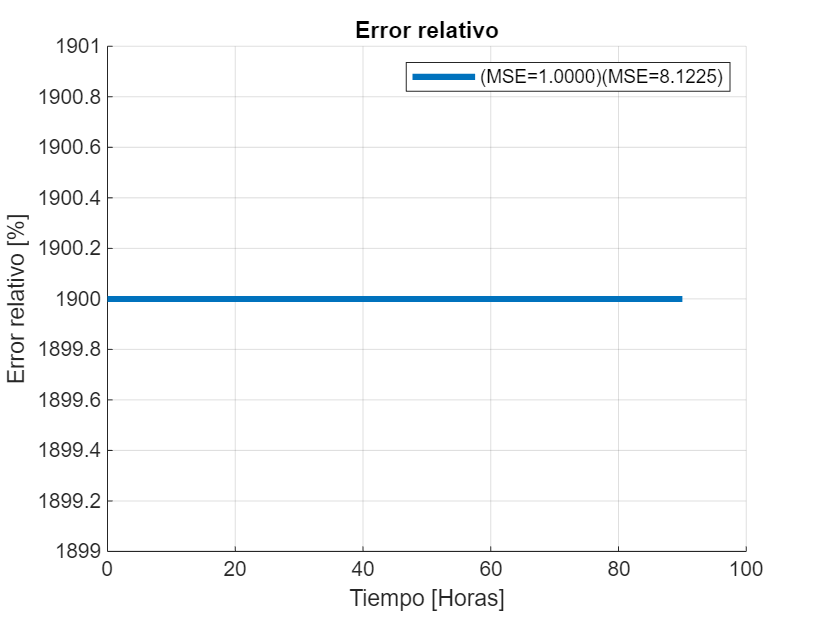


% Error relativo
fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
% ylim([0 100])
plot(time, getRelativeError(abs(error{1}), sustrate_vector_r), 'LineWidth', 3);

legend(sprintf('(MSE=%.4f)', params{1}, MSE{1}));


% Plano de fase
% fig = figure();
% set(fig,'Position',[0 0 800 600]);
% hold on; grid on;
% title('Plano de fase');
% xlabel('Concentración [g/g]');
% ylabel('Concentración [g/g]');
% plot(sustrates{1}, biomass{1}, 'LineWidth', 2);

% legend('Estados 1');

#### Conclusiones

No se llega al valor de referencia ya que lo que se hizo es cancelar la dinámica del sustrato, por lo que se queda estacionario, por lo que a continuación se implementa un término que compensa el error de manera proporcional

## Control linealizante con kp del error

Se agrega un término proporcional al error

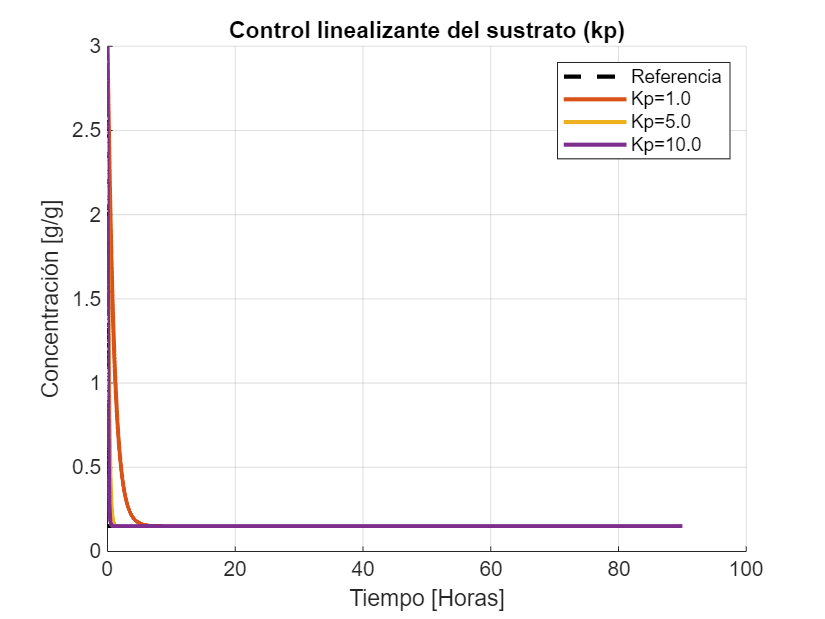

DatosModeloTP4

% referencia del sustrato (s*)
s_r=0.15; 

modelParameters.s_in=s_in;
modelParameters.s_r = s_r;
modelParameters.mu_r=mu_r;

params={1, 5, 10};
sustrates=cell(length(params));
error=cell(length(params));
MSE=cell(length(params));
for i=1:length(params)
    modelParameters.kp=params{i};

    sim_out = sim('simulaciones/TP4_control_linealizante_kp', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass = reshape(states(:,1), size(time));
    sustrates{i} = reshape(states(:,2), size(time));
    Do = sim_out.Do.Data;
    mu = sim_out.mu_s.Data;

    sustrate_vector_r = ones(length(sustrates{i}), 1)*s_r;
    
    error{i}=(sustrate_vector_r-sustrates{i});
    MSE{i} = immse(reshape(sustrate_vector_r, size(sustrates{i})), sustrates{i});

end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Control linealizante del sustrato (kp)');
xlabel('Tiempo [Horas]');
ylabel('Concentración [g/g]');
plot(time, sustrate_vector_r, 'k--', 'LineWidth', 2);
plot(time, sustrates{1}, 'LineWidth', 2);
plot(time, sustrates{2}, 'LineWidth', 2);
plot(time, sustrates{3}, 'LineWidth', 2);

legend('Referencia', ...
    sprintf('Kp=%.1f', params{1}), ...
    sprintf('Kp=%.1f', params{2}), ...
    sprintf('Kp=%.1f', params{3}));

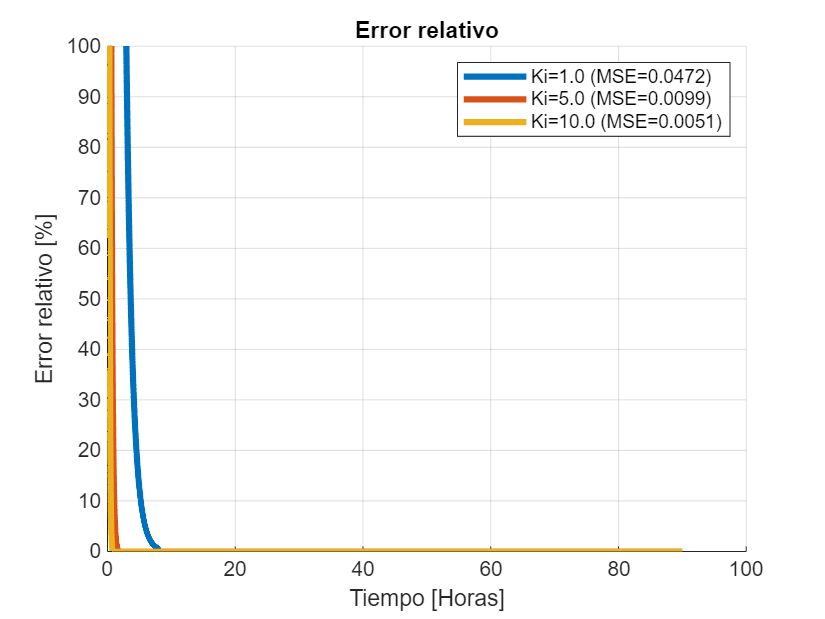


% Error relativo
fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error{1}), sustrate_vector_r), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{2}), sustrate_vector_r), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{3}), sustrate_vector_r), 'LineWidth', 3);

legend(sprintf('Ki=%.1f (MSE=%.4f)', params{1}, MSE{1}), ...
    sprintf('Ki=%.1f (MSE=%.4f)', params{2}, MSE{2}),...
    sprintf('Ki=%.1f (MSE=%.4f)', params{3}, MSE{3}));

#### Conclusiones

Ahora se tiene un convergencia a la referencia, y sin error a estado estacionario. Por lo que no habría necesidad de emplear otro termino integrativo.

## Control linealizante (sin kp) con variaciones en los parámetros

Que pasa si se tienen variaciones del 20% en los parámetros del controlador  (ks1) para el caso sin proporción ni integración del error.

### Variaciones en ks1

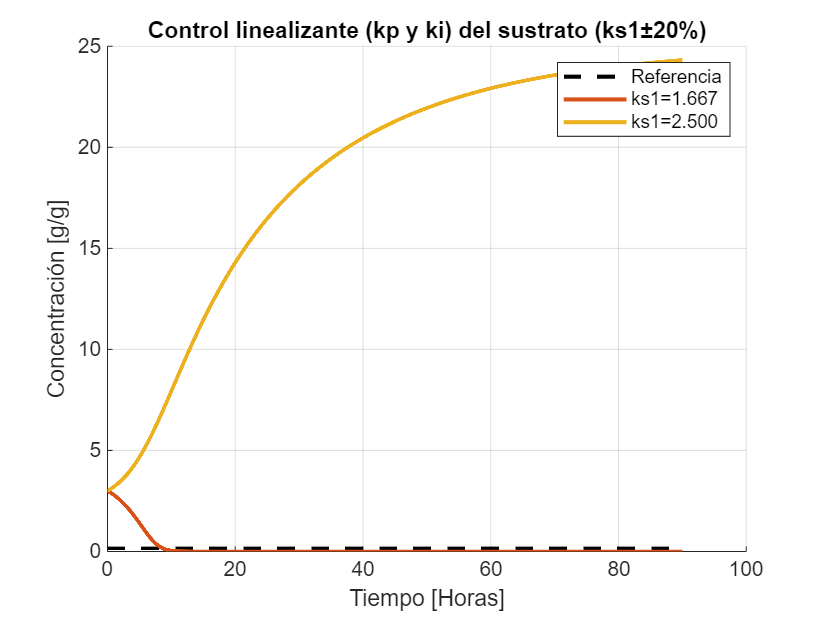

DatosModeloTP4

% referencia del sustrato (s*)
s_r=0.15; 

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.s_r = s_r;
modelParameters.mu_r=mu_r;

params={ks1*(0.8), ks1*(1.2)};
sustrates=cell(length(params));
biomass=cell(length(params));
error=cell(length(params));
MSE=cell(length(params));
for i=1:length(params)
    modelParameters.ks1 = params{i};

    sim_out = sim('simulaciones/TP4_control_linealizante', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass{i} = reshape(states(:,1), size(time));
    sustrates{i} = reshape(states(:,2), size(time));
    Do = sim_out.Do.Data;
    mu = sim_out.mu_s.Data;

    sustrate_vector_r = ones(length(sustrates{i}), 1)*s_r;
    
    error{i}=(sustrate_vector_r-sustrates{i});
    MSE{i} = immse(reshape(sustrate_vector_r, size(sustrates{i})), sustrates{i});

end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Control linealizante (kp y ki) del sustrato (ks1±20%)');
xlabel('Tiempo [Horas]');
ylabel('Concentración [g/g]');
plot(time, sustrate_vector_r, 'k--', 'LineWidth', 2);
plot(time, sustrates{1}, 'LineWidth', 2);
plot(time, sustrates{2}, 'LineWidth', 2);

legend('Referencia', ...
    sprintf('ks1=%.3f', params{1}), ...
    sprintf('ks1=%.3f', params{2}));

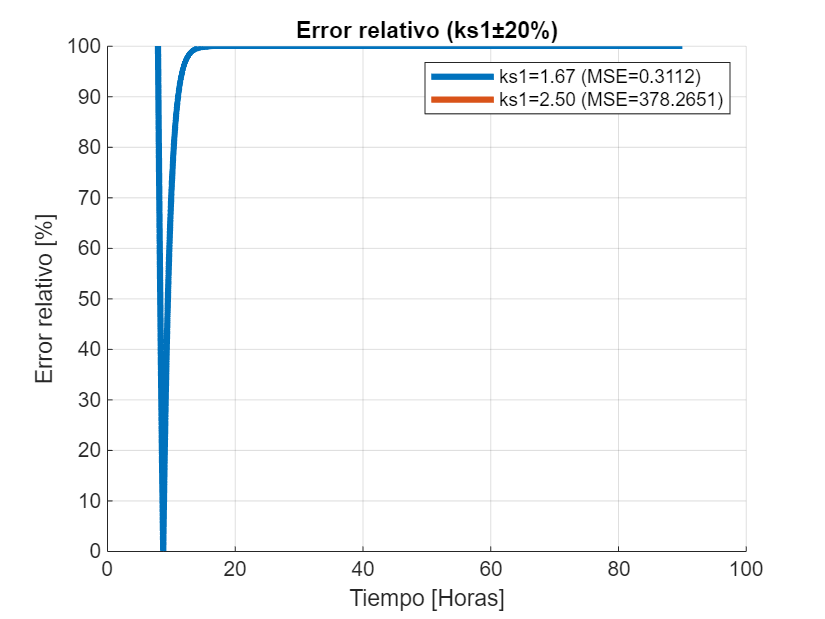


% Error relativo
fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo (ks1±20%)');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error{1}), sustrate_vector_r), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{2}), sustrate_vector_r), 'LineWidth', 3);

legend(sprintf('ks1=%.2f (MSE=%.4f)', params{1}, MSE{1}), ...
    sprintf('ks1=%.2f (MSE=%.4f)', params{2}, MSE{2}));

#### Conclusiones

Es muy dependiente de ks1. Varía demasiado. Ya que ahora la dinámica no se ve cancelada.

### Control linealizante (kp) con variaciones en los parámetros

Que pasa si se tienen variaciones del 20% en los parámetros del controlador

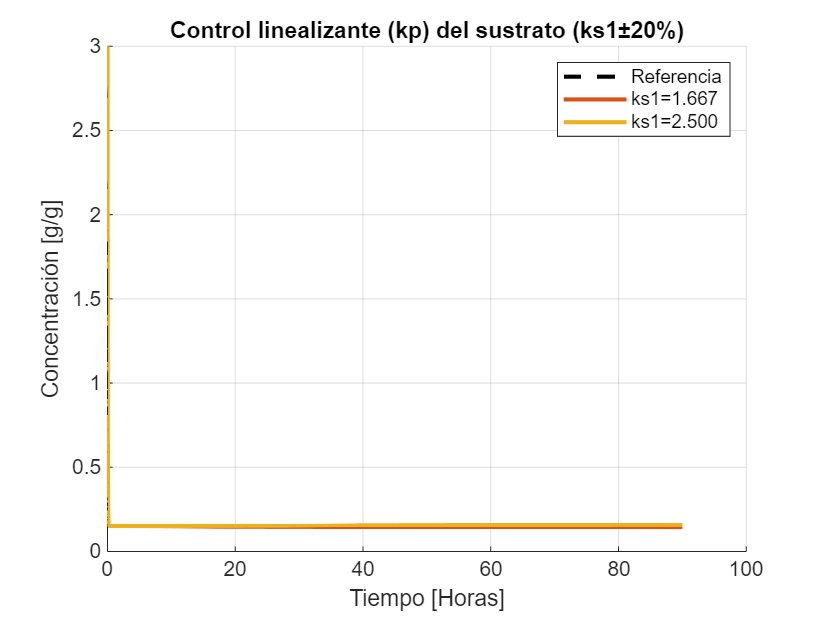

DatosModeloTP4

% referencia del sustrato (s*)
s_r=0.15; 

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.s_r = s_r;
modelParameters.mu_r=mu_r;
modelParameters.kp=30; % factor proporcional
% modelParameters.ki=10;
e0=1.5*s_r;

params={ks1*(0.8), ks1*(1.2)};
sustrates=cell(length(params));
biomass=cell(length(params));
error=cell(length(params));
MSE=cell(length(params));
for i=1:length(params)
    modelParameters.ks1 = params{i};

    sim_out = sim('simulaciones/TP4_control_linealizante_kp', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass{i} = reshape(states(:,1), size(time));
    sustrates{i} = reshape(states(:,2), size(time));
    Do = sim_out.Do.Data;
    mu = sim_out.mu_s.Data;

    sustrate_vector_r = ones(length(sustrates{i}), 1)*s_r;
    
    error{i}=(sustrate_vector_r-sustrates{i});
    MSE{i} = immse(reshape(sustrate_vector_r, size(sustrates{i})), sustrates{i});

end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Control linealizante (kp) del sustrato (ks1±20%)');
xlabel('Tiempo [Horas]');
ylabel('Concentración [g/g]');
plot(time, sustrate_vector_r, 'k--', 'LineWidth', 2);
plot(time, sustrates{1}, 'LineWidth', 2);
plot(time, sustrates{2}, 'LineWidth', 2);

legend('Referencia', ...
    sprintf('ks1=%.3f', params{1}), ...
    sprintf('ks1=%.3f', params{2}));

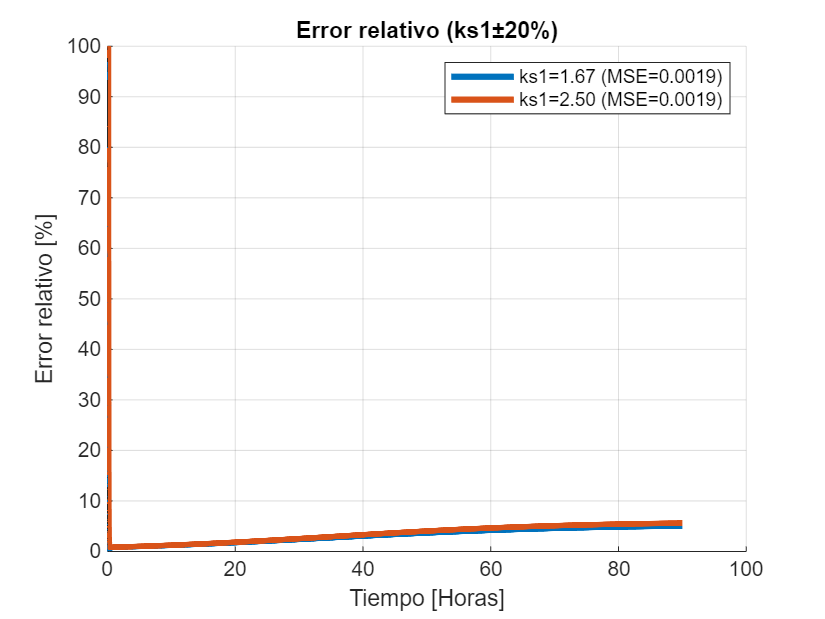


% Error relativo
fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo (ks1±20%)');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error{1}), sustrate_vector_r), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{2}), sustrate_vector_r), 'LineWidth', 3);

legend(sprintf('ks1=%.2f (MSE=%.4f)', params{1}, MSE{1}), ...
    sprintf('ks1=%.2f (MSE=%.4f)', params{2}, MSE{2}));

#### Conclusiones

Se tiene mayor robustez contra la variación del parámetros $k_{\textrm{s1}}$, pero ahora se tiene un error de estado estacionario, debido a que el controlador tiene que estar continuamente corrigiendo en error por la diferencia del modelo con error en los parámetros, por lo que ahora se añade un término integrativo que elimine este EEE

### Control linealizante (kp y ki) con variaciones en los parámetros

Que pasa si se tienen variaciones del 20% en los parámetros del controlador, pero ahora además se añade un término integrativo al controlador

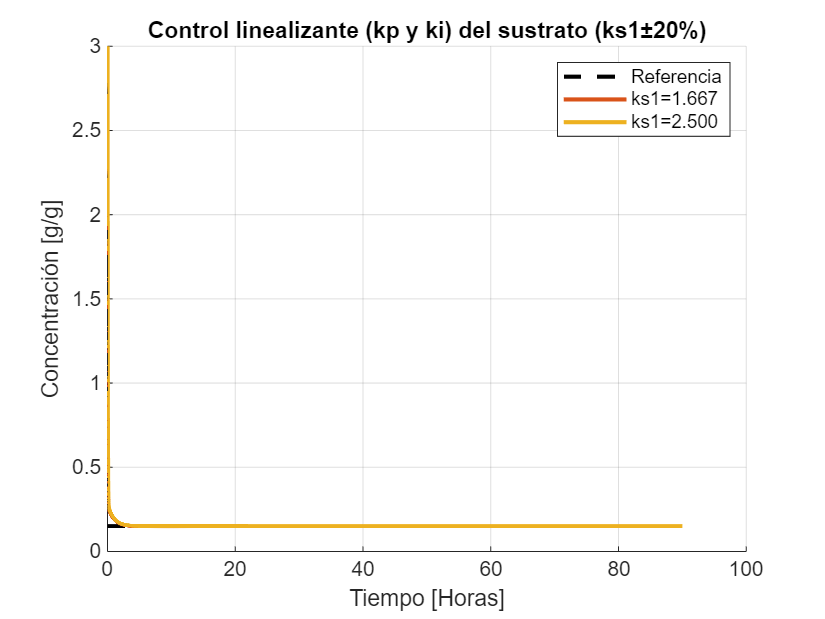

DatosModeloTP4

% referencia del sustrato (s*)
s_r=0.15; 

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.s_r = s_r;
modelParameters.mu_r=mu_r;
modelParameters.kp=30; % factor proporcional
modelParameters.ki=30;
e0=1.5*s_r;

params={ks1*(0.8), ks1*(1.2)};
sustrates=cell(length(params));
biomass=cell(length(params));
error=cell(length(params));
MSE=cell(length(params));
for i=1:length(params)
    modelParameters.ks1 = params{i};

    sim_out = sim('simulaciones/TP4_control_linealizante_ki', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass{i} = reshape(states(:,1), size(time));
    sustrates{i} = reshape(states(:,2), size(time));
    Do = sim_out.Do.Data;
    mu = sim_out.mu_s.Data;

    sustrate_vector_r = ones(length(sustrates{i}), 1)*s_r;
    
    error{i}=(sustrate_vector_r-sustrates{i});
    MSE{i} = immse(reshape(sustrate_vector_r, size(sustrates{i})), sustrates{i});

end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Control linealizante (kp y ki) del sustrato (ks1±20%)');
xlabel('Tiempo [Horas]');
ylabel('Concentración [g/g]');
plot(time, sustrate_vector_r, 'k--', 'LineWidth', 2);
plot(time, sustrates{1}, 'LineWidth', 2);
plot(time, sustrates{2}, 'LineWidth', 2);

legend('Referencia', ...
    sprintf('ks1=%.3f', params{1}), ...
    sprintf('ks1=%.3f', params{2}));

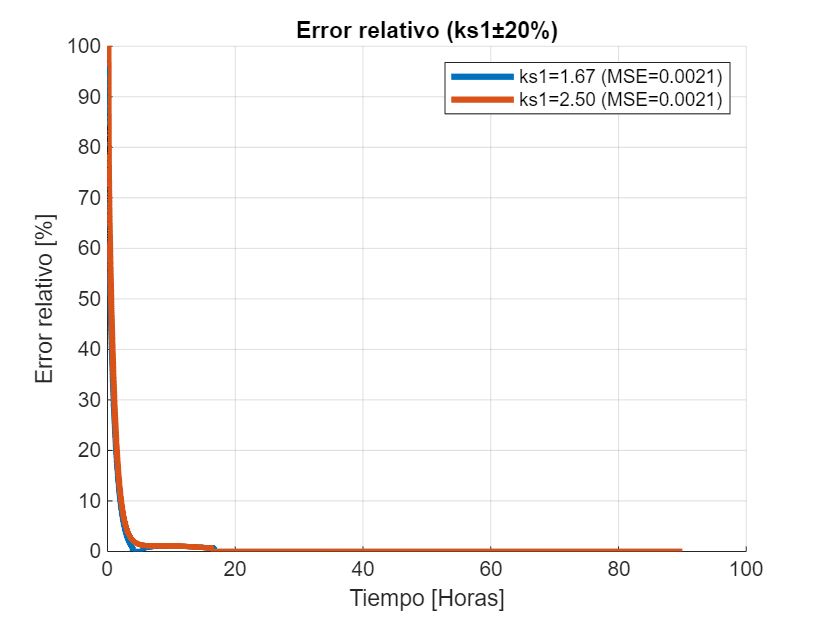


% Error relativo
fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo (ks1±20%)');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error{1}), sustrate_vector_r), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{2}), sustrate_vector_r), 'LineWidth', 3);

legend(sprintf('ks1=%.2f (MSE=%.4f)', params{1}, MSE{1}), ...
    sprintf('ks1=%.2f (MSE=%.4f)', params{2}, MSE{2}));

#### Conclusiones

Ahora se puede ver que debido al término integrativo se elimina el EEE y es además robusto ante variaciones del parámetro $k_{\textrm{s1}}$

## Caso: no se sabe el consumo de sustrato

El consumo de sustrato es $\mu \left(s\right)$, y se asume desconocido. Por lo que simplemente lo ignoro del controlador

### Solo con término proporcional al error

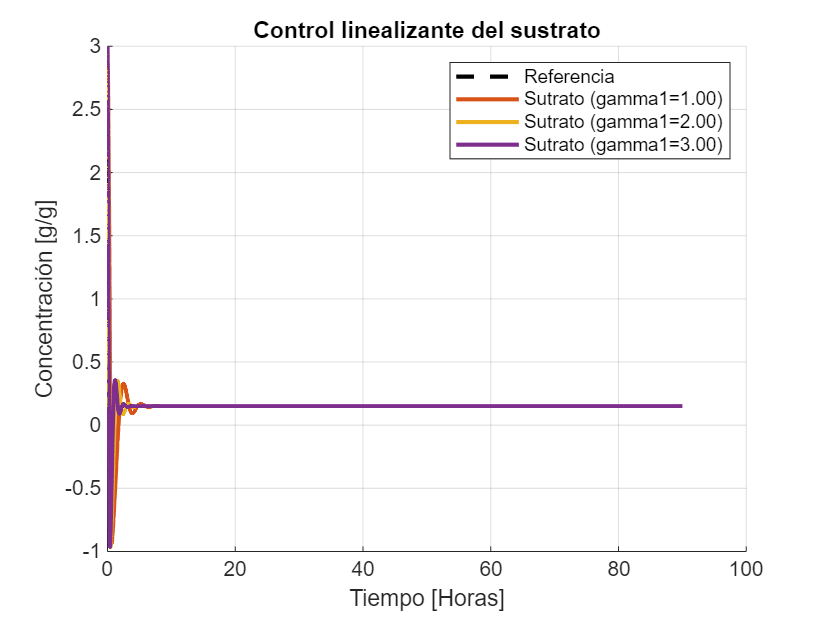

DatosModeloTP4

mu_est0=1.5*mu_r;

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.s_r = s_r;
modelParameters.mu_r=mu_r;

params={1, 2, 3};
sustrates=cell(length(params));
biomass=cell(length(params));
error=cell(length(params));
MSE=cell(length(params));
for i=1:length(params)
    modelParameters.gamma1 = params{i};

    sim_out = sim('simulaciones/TP4_control_linealizante_sin_mu', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass{i} = reshape(states(:,1), size(time));
    sustrates{i} = reshape(states(:,2), size(time));
    Do = sim_out.Do.Data;
    mu = sim_out.mu_s.Data;

    sustrate_vector_r = ones(length(sustrates{i}), 1)*s_r;
    
    error{i}=(sustrate_vector_r-sustrates{i});
    MSE{i} = immse(reshape(sustrate_vector_r, size(sustrates{i})), sustrates{i});

end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Control linealizante del sustrato');
xlabel('Tiempo [Horas]');
ylabel('Concentración [g/g]');
plot(time, sustrate_vector_r, 'k--', 'LineWidth', 2);
plot(time, sustrates{1}, 'LineWidth', 2);
plot(time, sustrates{2}, 'LineWidth', 2);
plot(time, sustrates{3}, 'LineWidth', 2);

legend('Referencia', ...
    sprintf('Sutrato (gamma1=%.2f)', params{1}), ...
    sprintf('Sutrato (gamma1=%.2f)', params{2}), ...
    sprintf('Sutrato (gamma1=%.2f)', params{3}));

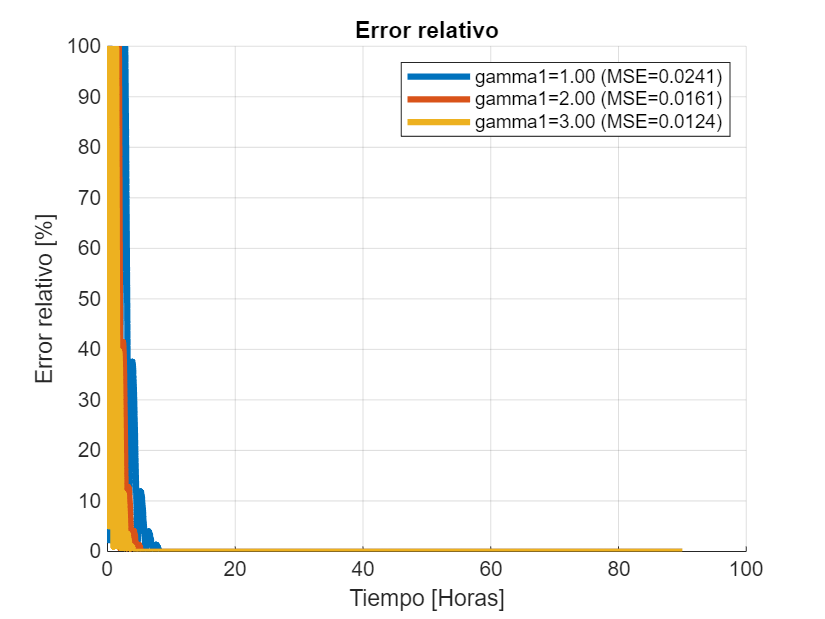


% Error relativo
fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error{1}), sustrate_vector_r), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{2}), sustrate_vector_r), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{3}), sustrate_vector_r), 'LineWidth', 3);

legend(sprintf('gamma1=%.2f (MSE=%.4f)', params{1}, MSE{1}), ...
    sprintf('gamma1=%.2f (MSE=%.4f)', params{2}, MSE{2}),...
    sprintf('gamma1=%.2f (MSE=%.4f)', params{3}, MSE{3}));

#### Conclusiones

Converge a un estado estacionario con error nulo al igual que el controlador linealizante anterior, esto se debe a que en realidad son muy parecidos, en implementación casi iguales, ambos poseen una proporcion e integración del error. Se puede ver que converge en 10 hs y se estaciona en el valor de referencia.

### Variaciones del parámetro ks1

Ahora se prueba que ocurre con el controlador cuando se varía ks1 en un 20%

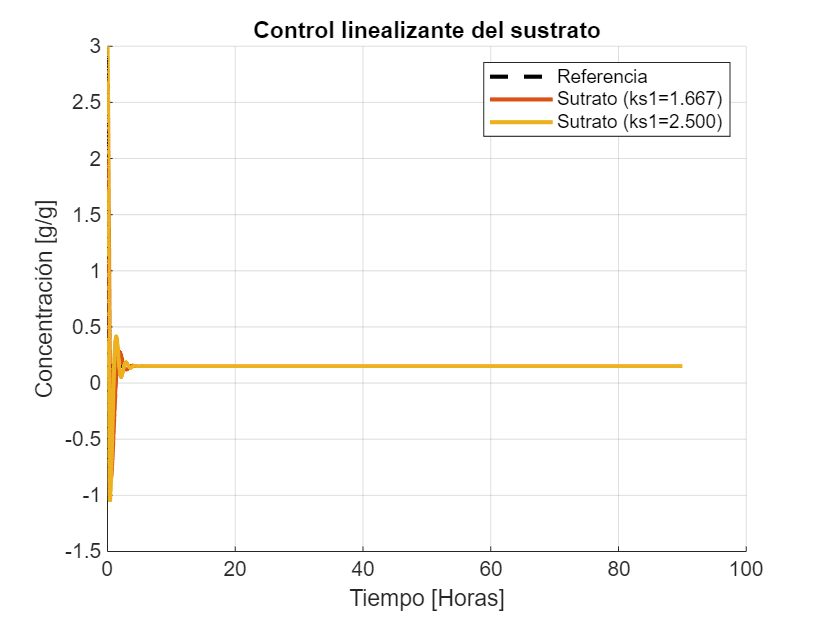

DatosModeloTP4

mu_est0=1.5*mu_r;

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.s_r = s_r;
modelParameters.mu_r=mu_r;
modelParameters.gamma1=2;

params={ks1*0.8, ks1*1.2};
sustrates=cell(length(params));
biomass=cell(length(params));
error=cell(length(params));
MSE=cell(length(params));
for i=1:length(params)
    modelParameters.ks1 = params{i};

    sim_out = sim('simulaciones/TP4_control_linealizante_sin_mu', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass{i} = reshape(states(:,1), size(time));
    sustrates{i} = reshape(states(:,2), size(time));
    Do = sim_out.Do.Data;
    mu = sim_out.mu_s.Data;

    sustrate_vector_r = ones(length(sustrates{i}), 1)*s_r;
    
    error{i}=(sustrate_vector_r-sustrates{i});
    MSE{i} = immse(reshape(sustrate_vector_r, size(sustrates{i})), sustrates{i});

end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Control linealizante del sustrato');
xlabel('Tiempo [Horas]');
ylabel('Concentración [g/g]');
plot(time, sustrate_vector_r, 'k--', 'LineWidth', 2);
plot(time, sustrates{1}, 'LineWidth', 2);
plot(time, sustrates{2}, 'LineWidth', 2);

legend('Referencia', ...
    sprintf('Sutrato (ks1=%.3f)', params{1}), ...
    sprintf('Sutrato (ks1=%.3f)', params{2}));

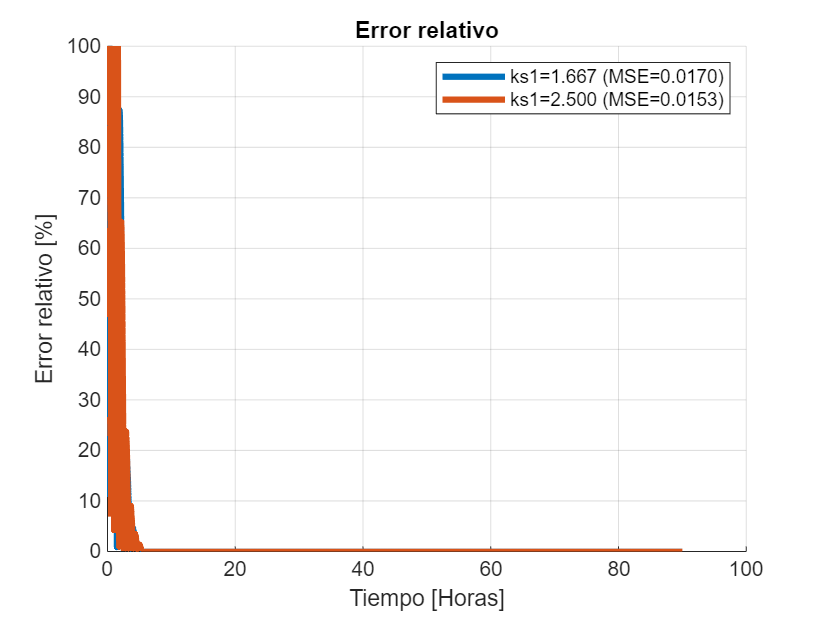


% Error relativo
fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error{1}), sustrate_vector_r), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{2}), sustrate_vector_r), 'LineWidth', 3);

legend(sprintf('ks1=%.3f (MSE=%.4f)', params{1}, MSE{1}), ...
    sprintf('ks1=%.3f (MSE=%.4f)', params{2}, MSE{2}));

#### Conclusiones

El controlador es robusto para el parámetro $k_{\textrm{s1}}$, pero para que así sea se tuvo que bajar la rapidéz con que converge a error nulo, pasando de un $\gamma_1$de 3 a 2, por lo que para variaciones de $k_{\textrm{s1}}$se necesita perder performance para ganar robustez. Pero aún converge con EEE nulo y tiempo aceptable.

### Robustez del controlador anterior

Ahora se verifica que tan bueno es este controlador, introduciendo perturbaciones en D del 20%. De esta manera podremos corroborar si el tomar $\mu \left(s\right)=1$es realmente una solución

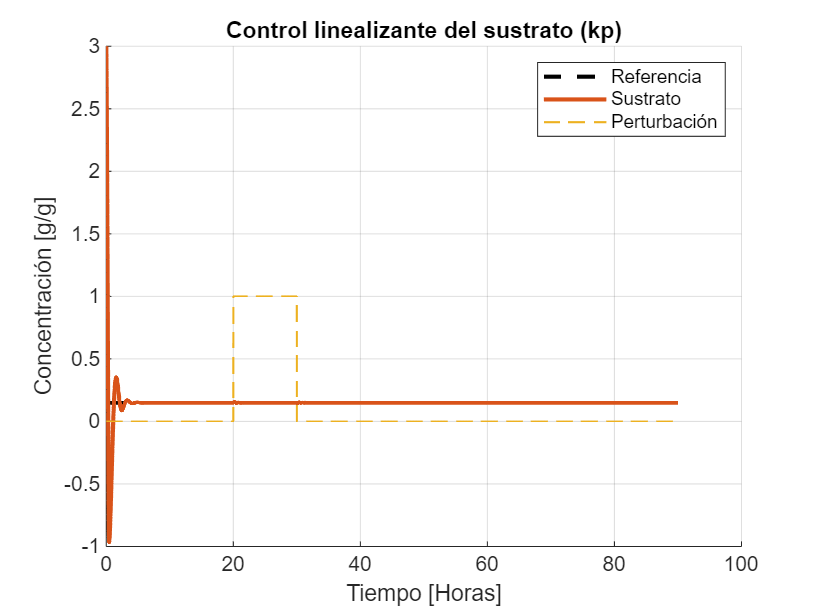

DatosModeloTP4

mu_est0=1.5*mu_r;

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.s_r = s_r;
modelParameters.mu_r=mu_r;

% Parámetros de la perturbación
disturbanceParameters.start = 20;
disturbanceParameters.end = 30;
disturbanceParameters.percentage = 0.2;

params={0};
sustrates=cell(length(params));
biomass=cell(length(params));
error=cell(length(params));
MSE=cell(length(params));
for i=1:length(params)

    sim_out = sim('simulaciones/TP4_control_linealizante_perturbanciones', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass{i} = reshape(states(:,1), size(time));
    sustrates{i} = reshape(states(:,2), size(time));
    Do = sim_out.Do.Data;
    mu = sim_out.mu_s.Data;
    disturbance = sim_out.disturbance.Data;

    sustrate_vector_r = ones(length(sustrates{i}), 1)*s_r;
    
    error{i}=(sustrate_vector_r-sustrates{i});
    MSE{i} = immse(reshape(sustrate_vector_r, size(sustrates{i})), sustrates{i});

end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Control linealizante del sustrato (kp)');
xlabel('Tiempo [Horas]');
ylabel('Concentración [g/g]');
plot(time, sustrate_vector_r, 'k--', 'LineWidth', 2);
plot(time, sustrates{1}, 'LineWidth', 2);
plot(time, disturbance/disturbanceParameters.percentage, '--', 'LineWidth', 1);

legend('Referencia', 'Sustrato', 'Perturbación');

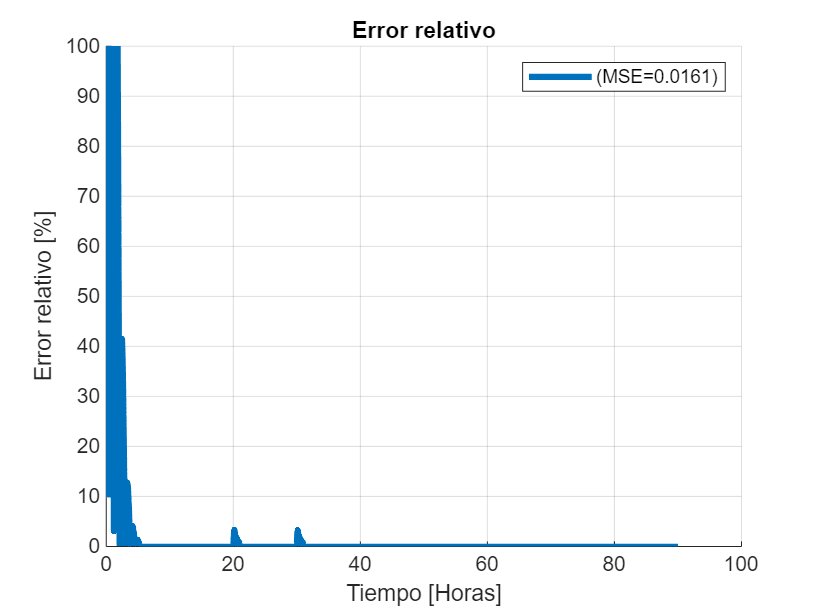


% Error relativo
fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error{1}), sustrate_vector_r), 'LineWidth', 3);

legend(sprintf('(MSE=%.4f)', MSE{1}));

#### Conclusiones

Como se puede observar, la perturbación afecta la salida, pero no de una manera muy significativa, por lo que este controlador es muy robusto y con rechazo a perturbaciones muy buenas.

## Simulación con el modelo completo

Ahora se emplea el controlador anterior, pero se simula empleando el modelo completo

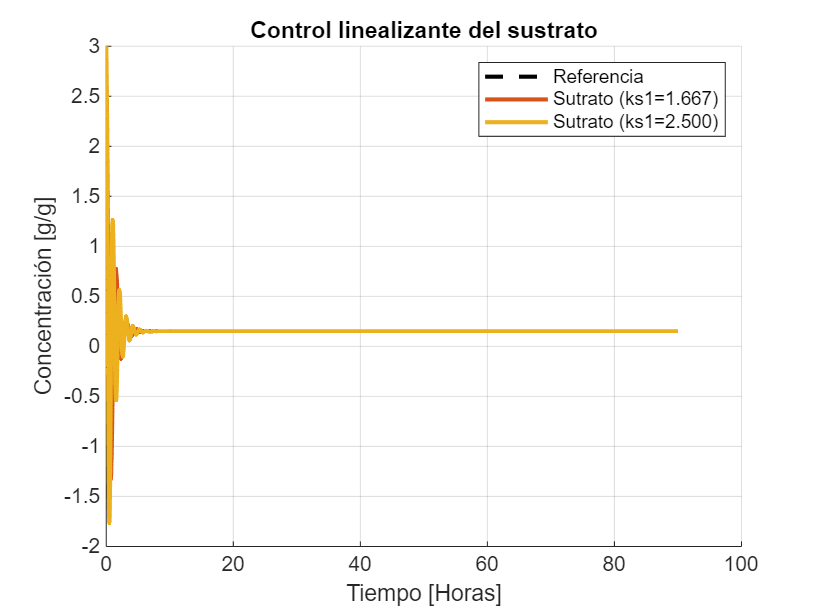

DatosModeloTP4

states0 = [x0;s0;0;0]*1.5;

modelParameters.K = [1 0;-ks1 -ks2; -kN 0; 0 ks2];
modelParameters.xi_in = [0;s_in;n_in;0];
modelParameters.ks1=ks1;
modelParameters.ks2=ks2;

modelParameters.mu_model.mu_max=0.46;
modelParameters.mu_model.Ks=1.2;
modelParameters.mu_model.Kis=16.728;
modelParameters.mu_model.Kn=0.254;

modelParameters.qp_model.qp_max=0.126;
modelParameters.qp_model.Kps=4.1;
modelParameters.qp_model.Kips=80;
modelParameters.qp_model.Kipn=0.262;

mu_est0=1.5*mu_r;

modelParameters.s_in=s_in;
modelParameters.x0=x0;
modelParameters.s_r = s_r;
modelParameters.mu_r=mu_r;
modelParameters.gamma1=2;

params={ks1*0.8, ks1*1.2};
sustrates=cell(length(params));
biomass=cell(length(params));
error=cell(length(params));
MSE=cell(length(params));
for i=1:length(params)
    modelParameters.ks1 = params{i};

    sim_out = sim('simulaciones/TP4_control_linealizante_mod_completo', simConfig);

    time = sim_out.tout;
    volume = sim_out.volume.Data;
    states = sim_out.states.Data;
    biomass{i} = reshape(states(:,1), size(time));
    sustrates{i} = reshape(states(:,2), size(time));
    Do = sim_out.Do.Data;
    mu = sim_out.mu_s.Data;

    sustrate_vector_r = ones(length(sustrates{i}), 1)*s_r;
    
    error{i}=(sustrate_vector_r-sustrates{i});
    MSE{i} = immse(reshape(sustrate_vector_r, size(sustrates{i})), sustrates{i});

end

fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Control linealizante del sustrato');
xlabel('Tiempo [Horas]');
ylabel('Concentración [g/g]');
plot(time, sustrate_vector_r, 'k--', 'LineWidth', 2);
plot(time, sustrates{1}, 'LineWidth', 2);
plot(time, sustrates{2}, 'LineWidth', 2);

legend('Referencia', ...
    sprintf('Sutrato (ks1=%.3f)', params{1}), ...
    sprintf('Sutrato (ks1=%.3f)', params{2}));

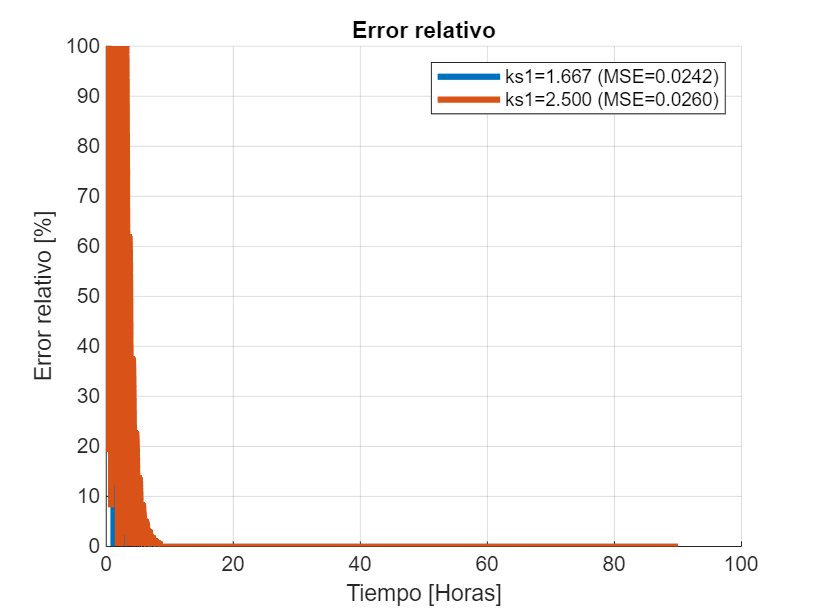


% Error relativo
fig = figure();
set(fig,'Position',[0 0 800 600]);
hold on; grid on;
title('Error relativo');
xlabel('Tiempo [Horas]');
ylabel('Error relativo [%]');
ylim([0 100])
plot(time, getRelativeError(abs(error{1}), sustrate_vector_r), 'LineWidth', 3);
plot(time, getRelativeError(abs(error{2}), sustrate_vector_r), 'LineWidth', 3);

legend(sprintf('ks1=%.3f (MSE=%.4f)', params{1}, MSE{1}), ...
    sprintf('ks1=%.3f (MSE=%.4f)', params{2}, MSE{2}));

#### Conclusiones

El controlador funciona perfectamente con el modelo completo, el cual incluye todos los estados y modelos cinéticos de rp y rx de Haldane